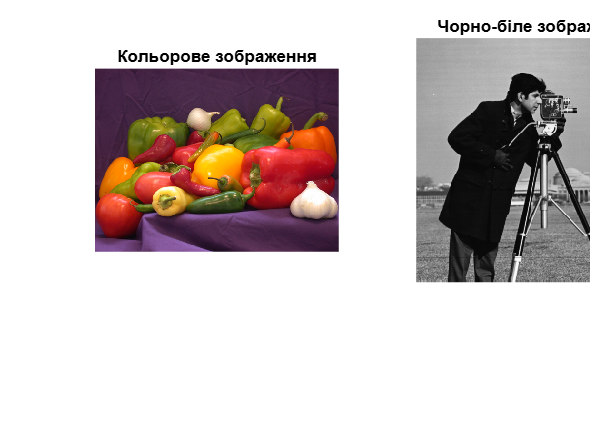

% Завантаження вбудованих зображень
I_color = imread('peppers.png'); % кольорове зображення
I_bw = imread('cameraman.tif'); % чорно-біле зображення

% Відображення оригінальних зображень
subplot(1,2,1), imshow(I_color), title('Кольорове зображення');
subplot(1,2,2), imshow(I_bw), title('Чорно-біле зображення');

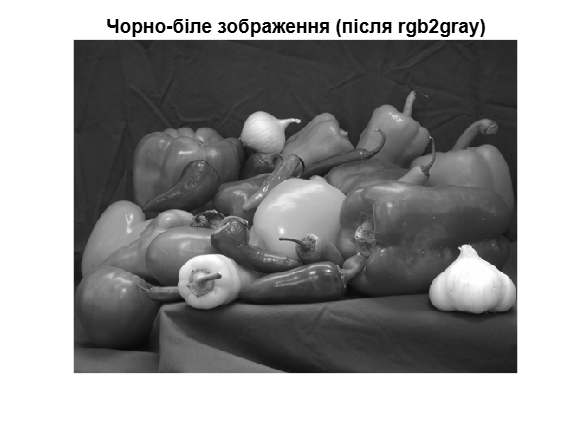


I_gray = rgb2gray(I_color);
figure, imshow(I_gray), title('Чорно-біле зображення (після rgb2gray)');

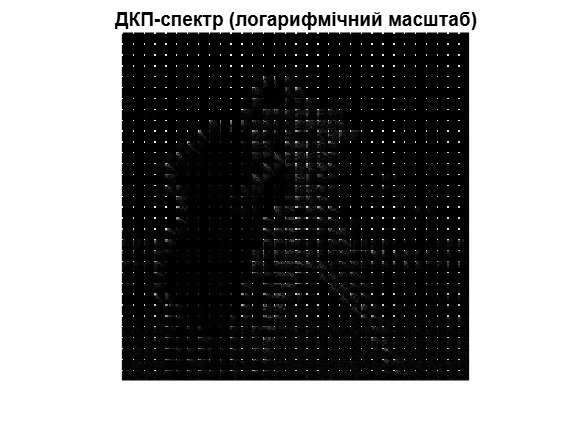


% Перетворення зображення в double
I = im2double(I_bw); 

% Створення матриці ДКП 8x8
T = dctmtx(8); 

% Функція для поблочного ДКП
dct = @(block_struct) T * block_struct.data * T';
B = blockproc(I, [8 8], dct); 

% Відображення ДКП-коефіцієнтів у логарифмічному масштабі
figure, imshow(log(abs(B) + 1), []), title('ДКП-спектр (логарифмічний масштаб)');

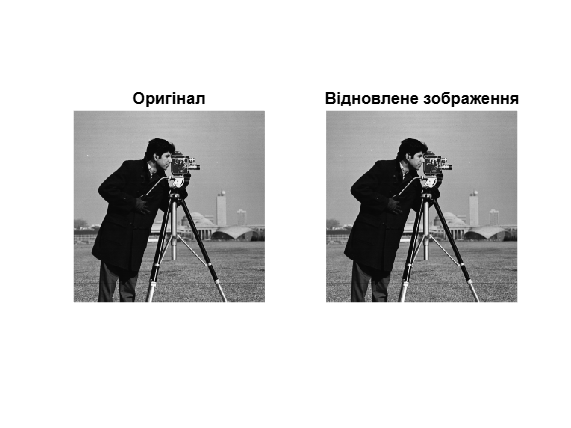


% Зворотне ДКП
invdct = @(block_struct) T' * block_struct.data * T;
I_reconstructed = blockproc(B, [8 8], invdct);

% Відображення оригіналу та відновленого зображення
figure;
subplot(1,2,1), imshow(I), title('Оригінал');
subplot(1,2,2), imshow(I_reconstructed), title('Відновлене зображення');

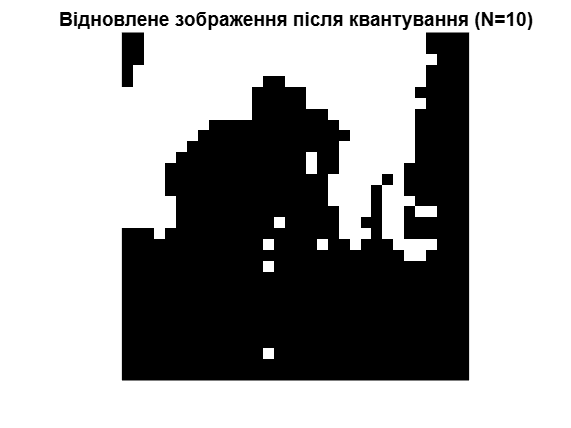


N = 10; % Крок квантування
B_quantized = N * round(B / N); % Квантування

% Відновлення після квантування
I_quantized = blockproc(B_quantized, [8 8], invdct);

% Відображення
figure;
imshow(I_quantized), title(['Відновлене зображення після квантування (N=', num2str(N), ')']);

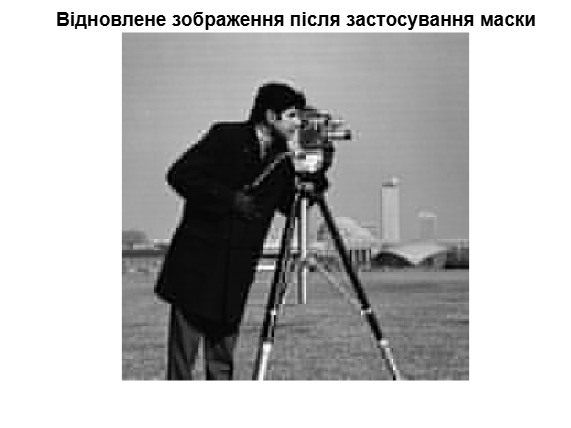


% Маска для квантування (зберігає НЧ коефіцієнти)
mask = [1 1 1 1 0 0 0 0;
        1 1 1 0 0 0 0 0;
        1 1 0 0 0 0 0 0;
        1 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0];

% Застосування маски до ДКП-коефіцієнтів
B_masked = blockproc(B, [8 8], @(block_struct) mask .* block_struct.data);

% Відновлення зображення
I_masked = blockproc(B_masked, [8 8], invdct);

% Відображення
figure;
imshow(I_masked), title('Відновлене зображення після застосування маски');